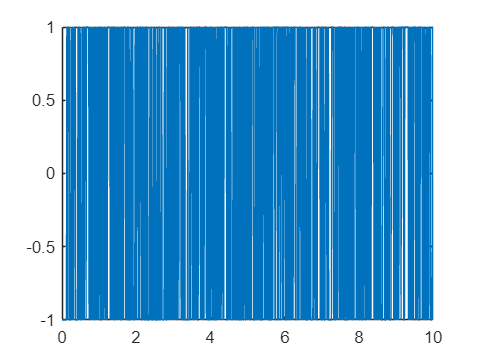

% 无输入系统 y(k+1) = ay(k) + bu(k)
%% 数据生成
clear
Ts = 0.01;
t = [0:Ts:10];
a = 1;  
M_seq = PRBS(t,13,a);
plot(t,M_seq)

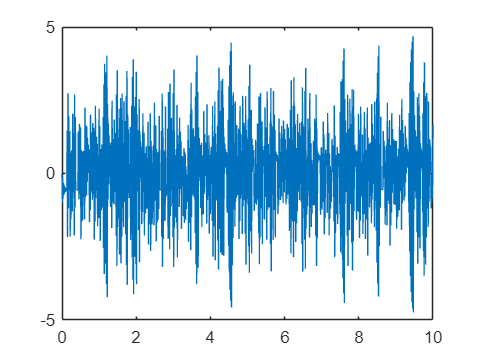


% 系统定义 
aa1 = -0.8;
b = 1;

u = M_seq;
y(1) = 0;
L = length(t);
for i = 1:(L-1)
    y(i+1) = aa1*y(i) + b*u(i);
end
plot(t,y)


%%% 最小二乘
Phi = [];
Y = [];
d = 1;
for k = d+1 : L
    phik = [y(k-1) u(k-1)];
    Phi = [Phi; phik];

    yk = y(k);
    Y = [Y;yk];
end

thetaE = inv(Phi'*Phi)*Phi'*Y

thetaE =    -0.8000
    1.0000


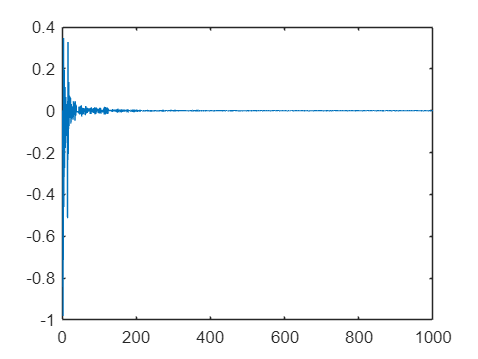


%% 递归最小二乘

P = 100*eye(2);   % Phik'*Phik的维数  % 为了让他收敛的慢一点用了0.1
% P = inv(Phi'*Phi);
thetaRLS = 0*ones(2,1);
% thetaRLS = thetaE;
phik = [0,0]';  % y(-1)  u(-1)
for i = 1:L-1
    % K 和 P 自己组成了一个动力学系统   且当P0很大时，这个系统是李雅普诺夫自稳定的
    K = P*phik/(1+phik'*P*phik);
    P = (eye(2) - K*phik')*P;
    % 注意要用y(i+1)去更新，而不是y(i)
    thetaRLS = thetaRLS + K*(y(i) - phik'*thetaRLS);

    phik = [y(i),u(i)]';  
    
    Krecoder{i} = K;
    Precoder{i} = P;
    thetaRLSrecoder{i} = thetaRLS;
end

for i = 1:length(Krecoder)
    KList(:,i) = Krecoder{i};
    Ptr(i) = trace(Precoder{i});
    thetaRLSList(:,i) = thetaRLSrecoder{i};
end 
plot(KList(1,:))

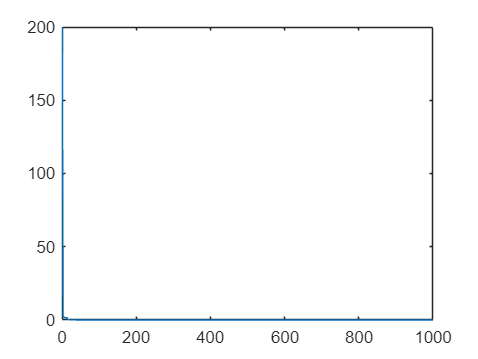

plot(Ptr)

thetaRLS

thetaRLS =    -0.8000
    1.0000


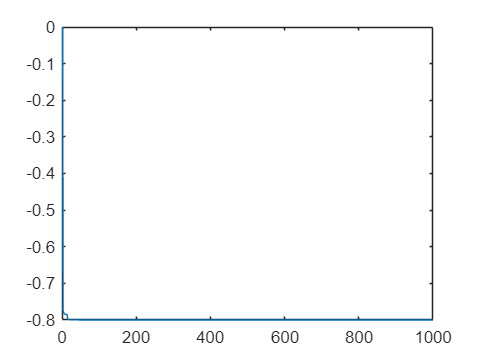

plot(thetaRLSList(1,:))

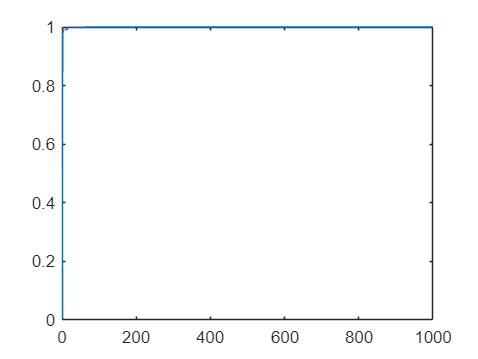

plot(thetaRLSList(2,:))

function Out = PRBS(t,n,a)
% a: the altitude of M-sequence, 
% t为生成的时间一共多长
% n用来控制一个PRBS序列的周期长度  一个周期＝2^n-1
% Generate a PRBS signal
% 1. 自相关性尽可能为δ函数（低相关性）。  2. 尽可能均匀分布(接近白噪声）  3. 但又要可被重复实现 
% n=4;                                % the number of registers
% L=15+1;                             % the length of M-sequence to be required   越长越接近白噪声
L = length(t);

for i = 1:n  Reg(i) = 1; end        % Initialize n registers  位移寄存器全1
Out(1)=-a;

for i=2:L
        temp=Reg(1);
        % 注意反馈抽头 可用GPT帮忙写
        % 抽头为第4、5、6、8级，异或结果反馈到第1级  仅适用于n = 8的情况
        % Reg(1) = xor(xor(xor(Reg(4), Reg(5)), Reg(6)), Reg(8)); 
        %% n = 13
        Reg(1) = xor(xor(xor(Reg(1), Reg(3)), Reg(4)), Reg(13));
        %%  仅适用于n= 4  情况
        % Reg(1)=xor(Reg(n-1),Reg(n));  % Modulo 2 adder   第一个寄存器 
        j=2;
        while j<=n                  % Registers shift                
             temp1=Reg(j);
             Reg(j)=temp;
             j=j+1;
             temp=temp1;
        end        
        Out(i)=Reg(n);
        if (Reg(n)==1)  Out(i) =-a; end
        if (Reg(n)==0)  Out(i)=a; end
end   

% stairs(Out); axis([1 L -0.5 1.5]);  % Plot the PRBS signal

end